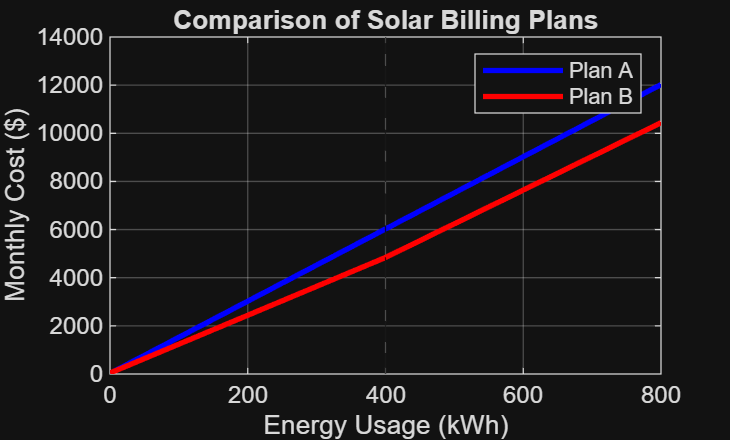

% Zulaikha Khan
% ES 115 Engineering Computer Applications
% Module 1 Project: Community Solar Billing Simulator 
% Instructor: Lynroy Grant 
% March 28, 2026
 
clear; clc; close all;

% Define usage values (kWh)
x = 0:25:800;

% Plan A (linear model)
BA = 15*x + 25;

% Plan B (piecewise model)
BB = zeros(size(x));

% For usage <= 400 kWh
BB(x <= 400) = 12*x(x <= 400) + 40;

% For usage > 400 kWh
BB(x > 400) = 14*x(x > 400) - 760;

% Plot both plans
figure;
plot(x, BA, 'b', 'LineWidth', 2); hold on;
plot(x, BB, 'r', 'LineWidth', 2);

% Show break point
xline(400, '--k');

title('Comparison of Solar Billing Plans');
xlabel('Energy Usage (kWh)');
ylabel('Monthly Cost ($)');
legend('Plan A', 'Plan B');
grid on;


% Find where plans are approximately equal
difference = BA - BB;
index = find(abs(difference) < 1e-2);

usage_equal = x(index);
cost_equal = BA(index);

disp('Where both plans cost the same (Usage, Cost):');

Where both plans cost the same (Usage, Cost):


disp([usage_equal' cost_equal']);

% Create table (first 10 rows shown)
T = table(x', BA', BB', 'VariableNames', {'Usage_kWh','PlanA','PlanB'});
disp('Sample table (first 10 rows):');

Sample table (first 10 rows):


disp(T(1:10,:));

    Usage_kWh    PlanA    PlanB
    _________    _____    _____

         0         25       40 
        25        400      340 
        50        775      640 
        75       1150      940 
       100       1525     1240 
       125       1900     1540 
       150       2275     1840 
       175       2650     2140 
       200       3025     2440 
       225       3400     2740 




disp('Sample table (first 10 rows):');

Sample table (first 10 rows):


disp(T(1:10,:));

    Usage_kWh    PlanA    PlanB
    _________    _____    _____

         0         25       40 
        25        400      340 
        50        775      640 
        75       1150      940 
       100       1525     1240 
       125       1900     1540 
       150       2275     1840 
       175       2650     2140 
       200       3025     2440 
       225       3400     2740 




% Find where Plan B is cheaper
index_B = find(BB < BA);

% Find where Plan A is cheaper
index_A = find(BA < BB);

% Display exact usage ranges
fprintf('Plan B is cheaper from %d kWh to %d kWh\n', min(x(index_B)), max(x(index_B)));

Plan B is cheaper from 25 kWh to 800 kWh


fprintf('Plan A is cheaper from %d kWh to %d kWh\n', min(x(index_A)), max(x(index_A)));

Plan A is cheaper from 0 kWh to 0 kWh
